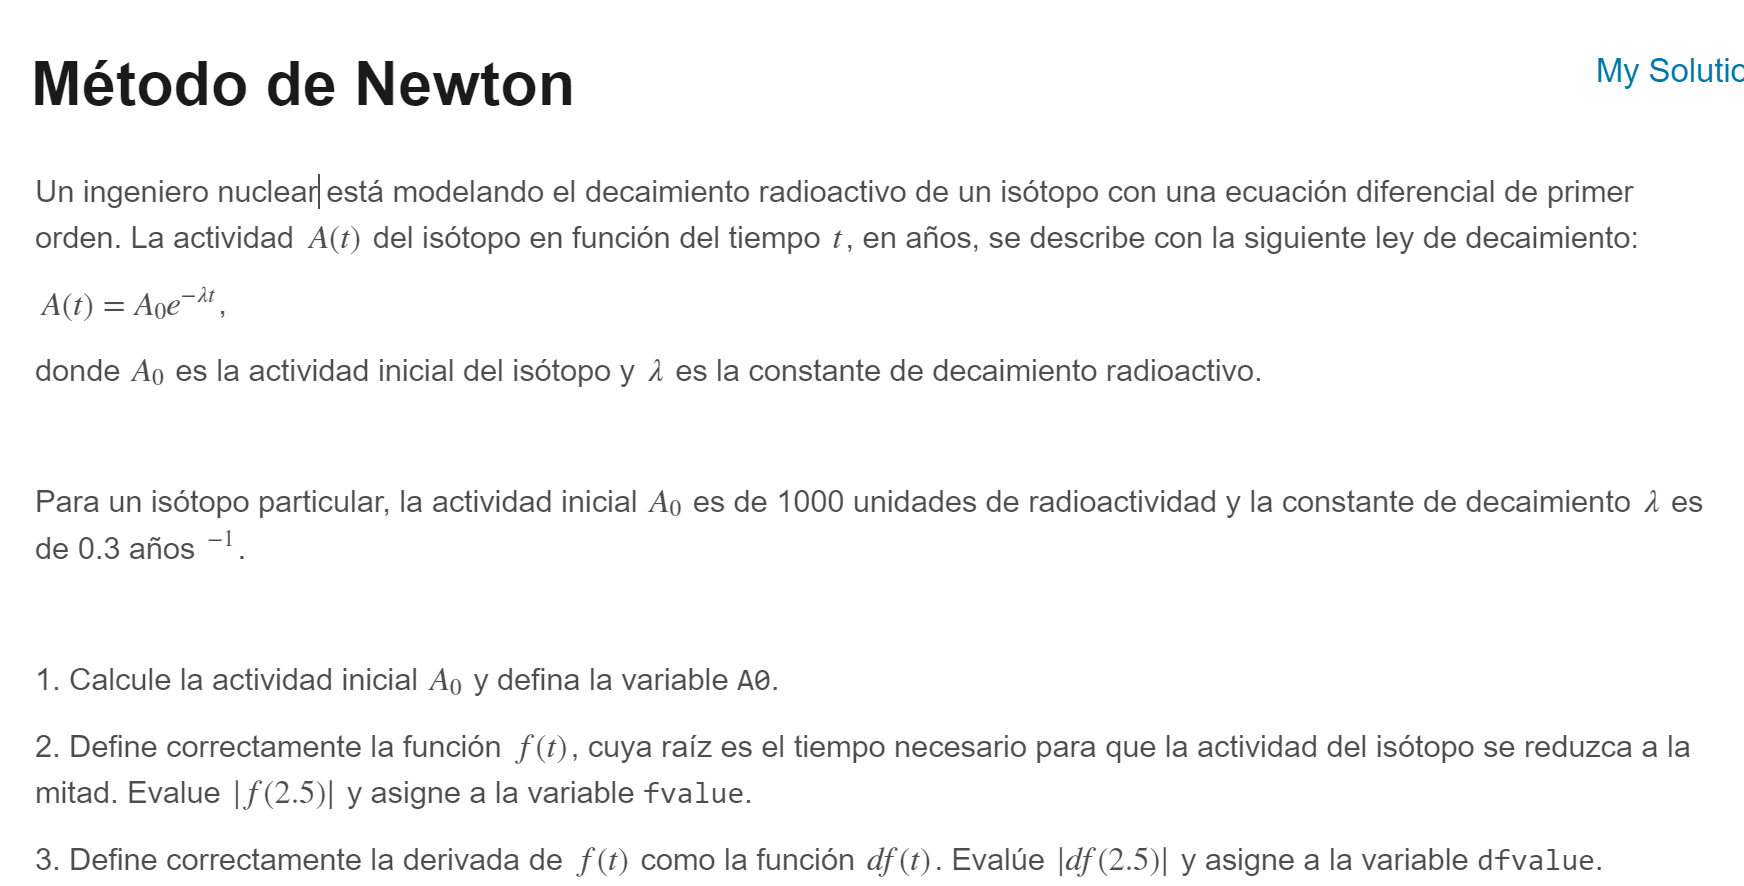

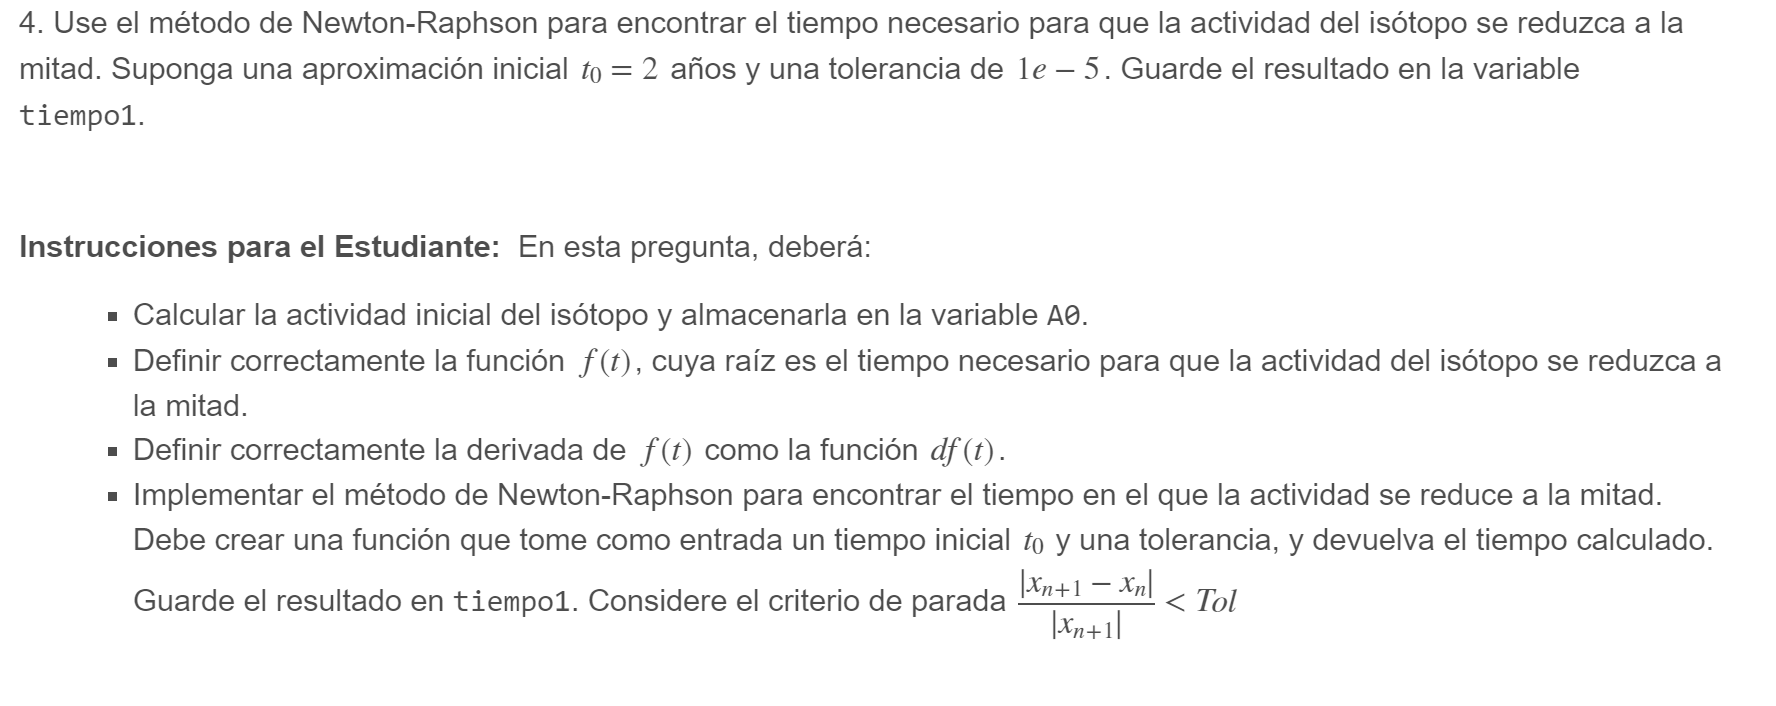

syms t

A0 = 1000; % unidades de radioactividad
lambda = 0.3; % constante de decaimiento
% función a encontrar la raíz
f = @(t) A0 * exp( -1*lambda*t) - 500;
fvalue= abs(f(2.5));
%La derivada de la función
df = matlabFunction(diff(f,t));
dfvalue=abs(df(2.5)); 
tiempo1 = newton_raphson(f,df,2, 1e-5); % calcular el tiempo de reducción a la mitad
%Método de Newton-Raphson para encontrar el tiempo de reducción a la mitad
function t_half = newton_raphson(f,df,t0, tol)

  error = 1;
  t1 = 1;

  while error > tol
      t1 = t0 - f(t0)/ df(t0);      
      error = abs(t1-t0)/abs(t1);
      t0 = t1;
  end

  t_half = t1;

end